structure_stl = "structure.stl";
print_stl = "print.stl";

% How much to translate the structure
ts = [0 0 0];
% How much to rotate the structure
rs = [-90 0 0];

% How much to translate the print
tp = [0 0 50.8-19.04];
% How much to rotate the print
rp = [-90 0 0];

% 1 means all inputs are in degrees
deg = 1;

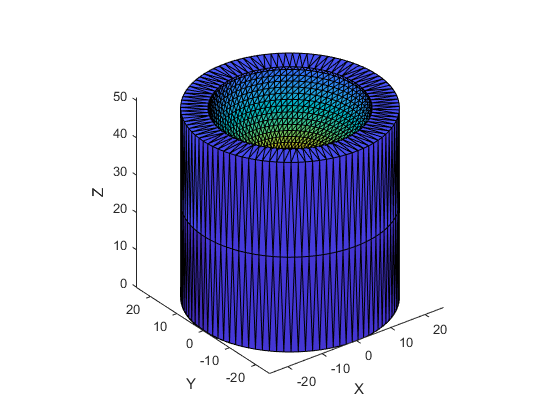

[Ps,Ts,Ns]=import_stl_fast(structure_stl,1);

[Ps, Ns] = rotate_mesh(Ps,Ns,rs,deg);
Ps = translate_mesh(Ps,ts);

patch('Faces', Ts, 'Vertices', Ps, 'FaceVertexCData', (1:length(Ts(:,1)))', 'FaceColor', 'flat');
view(3)
axis equal
zlabel('Z');xlabel('X');ylabel('Y');

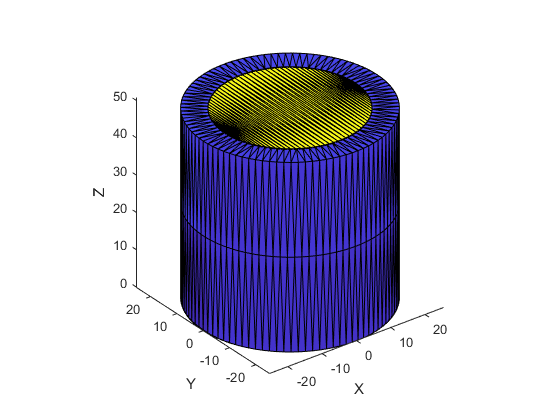

[Pp,Tp,Np]=import_stl_fast(print_stl,1);

[Pp,Np] = rotate_mesh(Pp,Np,rp,deg);
Pp = translate_mesh(Pp,tp);

patch('Faces', Tp, 'Vertices', Pp, 'FaceVertexCData', (1:length(Tp(:,1)))', 'FaceColor', 'flat');

% See [1]Bin Huang, “Development of a Software procedure for Curved layered Fused DepositionModelling (CLFDM),” Master Thesis, Auckland University of Technology, 2009.
% Implementation of MFVCP
% lPs = length(Ps(:,1))

lPs = 2008

% V1 = Ps(1:lPs-2,1:3)-Ps(2:lPs-1,1:3)

V1 =          0   -0.0000  -50.8000
   -0.0139   -0.8398   25.4000
         0    1.6796         0
   -0.0416   -2.5185   25.4000
         0    3.3574   -0.0000
         0   -3.3574  -50.8000
         0    3.3574         0
   -0.0694   -4.1945   25.4000
         0    5.0315         0
   -0.0970   -5.8658   25.4000


% V2 = Ps(3:lPs,1:3)-Ps(2:lPs-1,1:3)

V2 =     0.0139    0.8398  -25.4000
         0   -1.6796         0
    0.0416    2.5185  -25.4000
         0   -3.3574    0.0000
         0    3.3574   50.8000
         0   -3.3574         0
    0.0694    4.1945  -25.4000
         0   -5.0315         0
    0.0970    5.8658  -25.4000
         0   -6.7001    0.0000


% V3 = repmat([0 1 0],length(V2(:,1)),1)

V3 =      0     1     0
     0     1     0
     0     1     0
     0     1     0
     0     1     0
     0     1     0
     0     1     0
     0     1     0
     0     1     0
     0     1     0


% cV13 = cross(V1,V3)

cV13 =    50.8000         0         0
  -25.4000         0   -0.0139
         0         0         0
  -25.4000         0   -0.0416
    0.0000         0         0
   50.8000         0         0
         0         0         0
  -25.4000         0   -0.0694
         0         0         0
  -25.4000         0   -0.0970


% cV32 = cross(V3,V2)

cV32 =   -25.4000         0   -0.0139
         0         0         0
  -25.4000         0   -0.0416
    0.0000         0         0
   50.8000         0         0
         0         0         0
  -25.4000         0   -0.0694
         0         0         0
  -25.4000         0   -0.0970
    0.0000         0         0


% t=5

t = 5

% V13 = t*(cV13./(vecnorm(cV13')'))

V13 =     5.0000         0         0
   -5.0000         0   -0.0027
       NaN       NaN       NaN
   -5.0000         0   -0.0082
    5.0000         0         0
    5.0000         0         0
       NaN       NaN       NaN
   -5.0000         0   -0.0137
       NaN       NaN       NaN
   -5.0000         0   -0.0191


% V23 = t*(cV32./(vecnorm(cV32')'))

V23 =    -5.0000         0   -0.0027
       NaN       NaN       NaN
   -5.0000         0   -0.0082
    5.0000         0         0
    5.0000         0         0
       NaN       NaN       NaN
   -5.0000         0   -0.0137
       NaN       NaN       NaN
   -5.0000         0   -0.0191
    5.0000         0         0


% dot(V13,V23,2)

ans =   -25.0000
       NaN
       NaN
  -25.0000
   25.0000
       NaN
       NaN
       NaN
       NaN
  -24.9998


% alpha = acos(dot(V13,V23,2)./(vecnorm(V13')'.*vecnorm(V23')'))

alpha =     3.1410
       NaN
       NaN
    3.1400
         0
       NaN
       NaN
       NaN
       NaN
    3.1378


% V5 = t*(V13+V23)./(cos(alpha/2).*(vecnorm(V13')'.*vecnorm(V23')'))

V5 =     0.0005         0   -2.0000
       NaN       NaN       NaN
       NaN       NaN       NaN
    0.0016         0   -2.0000
    2.0000         0         0
       NaN       NaN       NaN
       NaN       NaN       NaN
       NaN       NaN       NaN
       NaN       NaN       NaN
    0.0038         0   -2.0000


% Ps2 = V5+Ps(2:lPs-1,:)

Ps2 =   -25.3995    0.0000   48.8000
       NaN       NaN       NaN
       NaN       NaN       NaN
  -25.3428    1.6787   -2.0000
  -23.3445   -1.6787   -0.0000
       NaN       NaN       NaN
       NaN       NaN       NaN
       NaN       NaN       NaN
       NaN       NaN       NaN
  -25.1743    3.3501   -2.0000


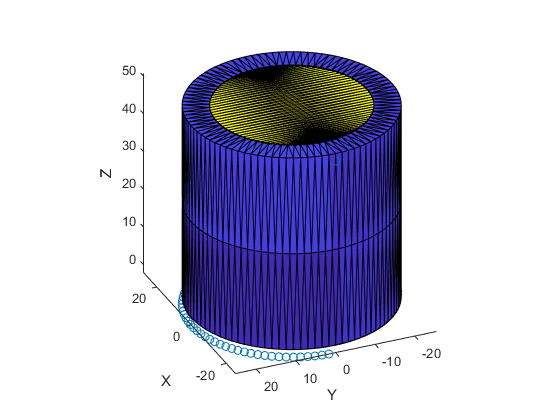

% patch('Faces', Ts, 'Vertices', Ps, 'FaceVertexCData', (1:length(Ts(:,1)))', 'FaceColor', 'flat');
% view(3)
% axis equal
% zlabel('Z');xlabel('X');ylabel('Y');
% hold on
% scatter3(Ps2(:,1),Ps2(:,2),Ps2(:,3))